% example of dct denoising
clear
close all

% load the image and rescale it in [0,1]
%img = im2double(imread('cameraman.tif'));
%img = checkerboard(16, 8, 8);
%img = circshift(img, [1,1]);
%img = im2double(imread('BM3D_images/barbara.png'));
img = im2double(imread('BM3D_images/Lena512.png'));
sizes = size(img)

sizes =    512   512


% noise level
sigma_noise = 20/255;

%patch size
p = 8;

% corrupt the image with white gaussian noise
noisy_img = img + random('normal', 0, sigma_noise, size(img));

% compute the PSNR of the noisy input
psnr_noisy = 10 * log10(sizes(1)*sizes(2)/sum((img - noisy_img).^2,'all'))

psnr_noisy = 22.1028

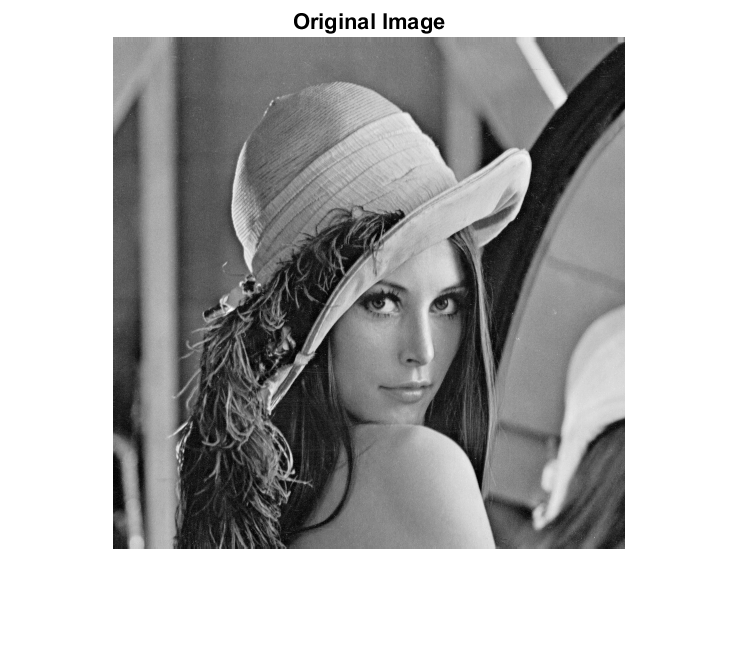


figure(1), imshow(img,[]), title('Original Image')

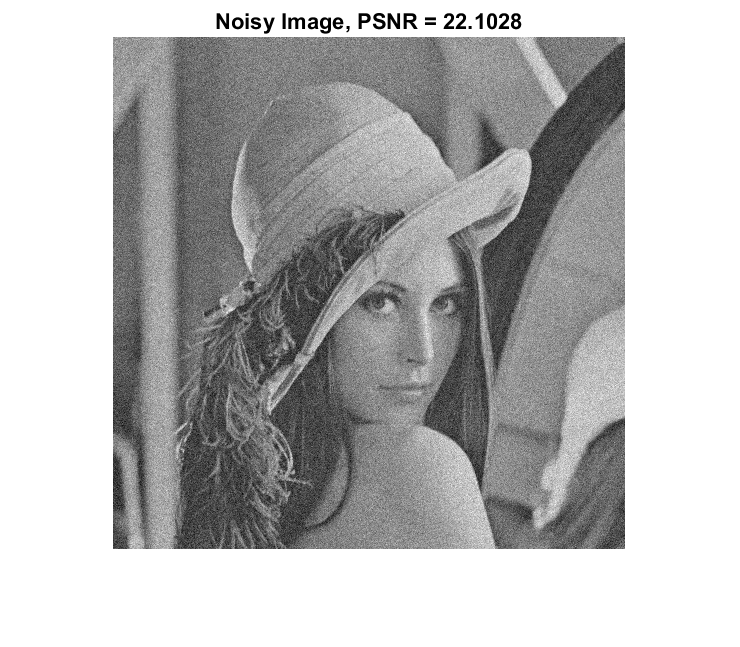

figure(2), imshow(noisy_img,[]), title(['Noisy Image, PSNR = ',num2str(psnr_noisy)])

## generate the dct basis

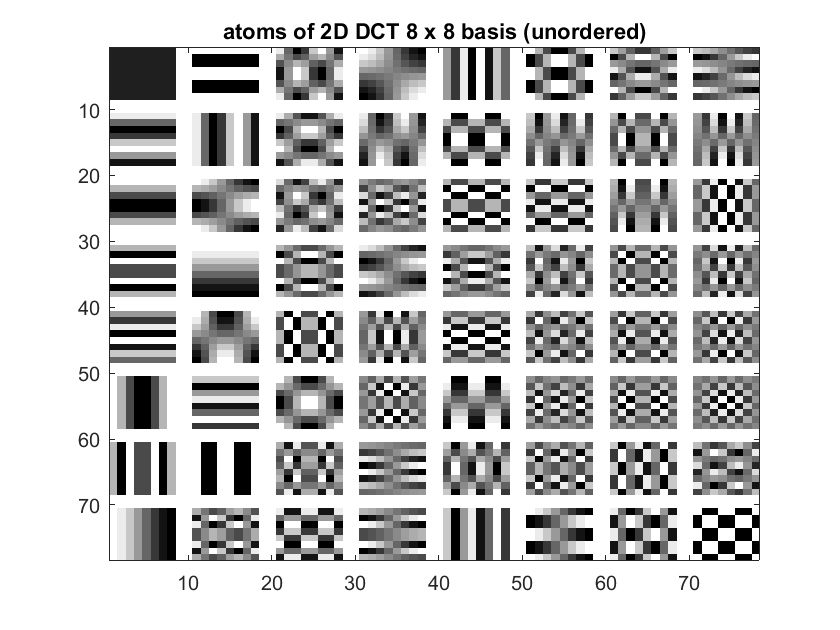

D = zeros(p^2,p^2);

for ii=1:p^2
    patch = zeros(p,p);
    patch(ii) = 1;
    atom = idct2(patch);
    D(:,ii) = atom(:);
end

% display the 2D-DCT basis 
figure(), show_dictionary(D);
title(['atoms of 2D DCT ', num2str(p) ,' x ', num2str(p) , ' basis (unordered)'])

## denoising

% initialize the estimated images
img_hat = zeros(size(noisy_img));

% initialize the weight matrix
weights = zeros(size(noisy_img));

% set the threshold for the Hart Thresholding
tau = 3 * sigma_noise; % Donoho says: sigma * sqrt(2*log(p^2))
%tau = sigma_noise * sqrt(2*log(p^2));
% define the step (=p for non overlapping patches)
STEP = 1; 

tic
% operates patch-wise
for ii = 1 : STEP : (size(noisy_img,1)-p+1)
    for jj=1 : STEP : (size(noisy_img,1)-p+1)
        % extrach the patch with the top left corner at pixel (ii, jj)
        s  = noisy_img(ii:ii+p-1, jj:jj+p-1);
        
        % compute the representation w.r.t. the DCT dictionary
        x = dct2(s);
        
        % perform Hard Thresholding (do not HT the dc component!)
        xh = (abs(x)>tau).*x;
        if xh(1) == 0
            xh(1) = x(1);
        end
        x = xh;
        
        % perform the reconstruction
        s_hat = idct2(x); 
        
        % compute the weight for the reconstructed patch
        w =ones(p)./sum(abs(x)>0, 'all'); %norm0
        %w =ones(p); %uniform
        
        % put the reconstructed patch in the estimated image using the computed weight
        % UPDATE img_hat
        
        img_hat(ii:ii+p-1, jj:jj+p-1) = img_hat(ii:ii+p-1, jj:jj+p-1) + s_hat.*w;
        
        % store the weight of the current patch in the weight matrix
        % UPDATE weights
        weights(ii:ii+p-1, jj:jj+p-1) = weights(ii:ii+p-1, jj:jj+p-1) + w; 
    end
end
toc

Elapsed time is 45.166938 seconds.



% normalize the estimated image with the computed weights
img_hat = img_hat./weights;

% compute the psnr of the estimated image
psnr_hat = 10 * log10(sizes(1)*sizes(2)/sum((img_hat-img).^2,'all'))

psnr_hat = 31.9679

str = sprintf('PSNR : %2.3f', psnr_hat);
disp(['\n', str, '\n'])

\nPSNR : 31.968\n


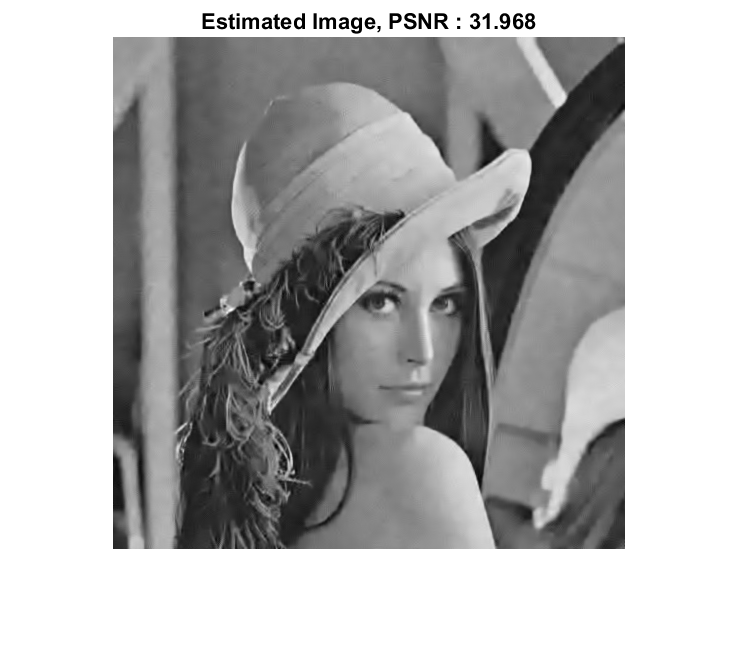

figure(3), imshow(img_hat,[]), title(['Estimated Image, ', str])

## compare denoising by DCT agaist smoothing by convolution

define a filter that by convolution returns the average over a 5x5 region h = compute the convolution of the noisy image against the averaging filter img_hat_conv = 

h = ones(5)/25;
% define the step (=p for non overlapping patches)
img_hat_conv = conv2(noisy_img,h,'same');


% compute PSNR
psnr_hat_conv = 10 * log10(sizes(1)*sizes(2)/sum((img_hat_conv - img).^2, 'all'));
str = sprintf('PSNR : %2.3f', psnr_hat_conv);
disp(['\n', str, '\n'])

\nPSNR : 27.591\n


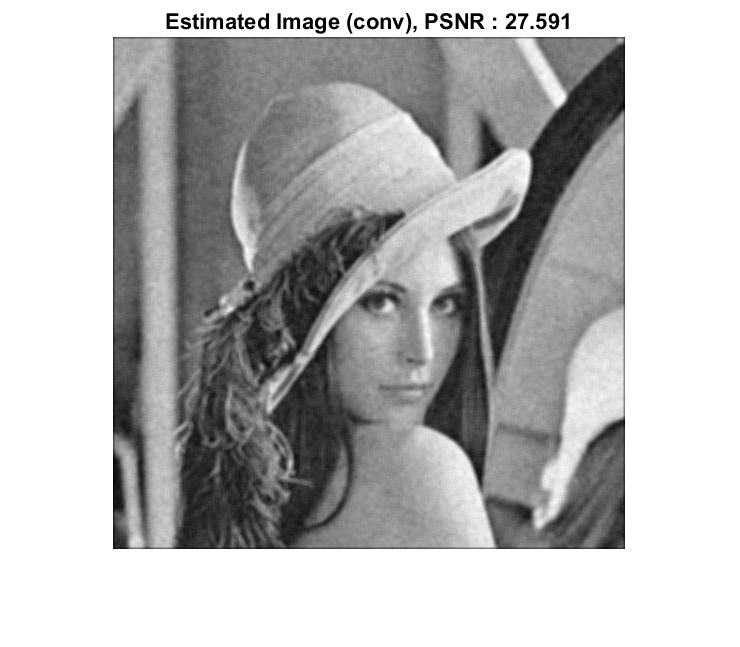


% display the resulting image and check the loss of details
figure(4),
imshow(img_hat_conv,[]), title(['Estimated Image (conv), ', str])

## noise estimation

% define the horizontal derivative filter
h = [1 -1];
% convolve the noisy_img and the filter
convo = conv2(noisy_img, h, "same");
% compute sigma as the empirical std
M = mean(convo, "all");

sigma_hat_emp = sum((convo - M).^2, "all")/(2*sizes(1)*sizes(2));


% compute sigma using Median of Absolute Deviation
sigma_hat = median(abs(convo), "all")/(0.6749*sqrt(2));
fprintf('sigma: %.3f', sigma_noise)

sigma: 0.078

fprintf('sigma_hat (empirical std): %.3f', sigma_hat_emp)

sigma_hat (empirical std): 0.011

fprintf('sigma_hat (MAD): %.3f', sigma_hat)

sigma_hat (MAD): 0.087